# Rocky Project

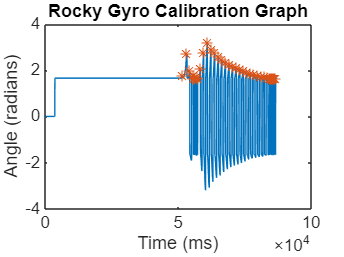

load("rocky_gyro_cal_2.mat")
angle = p;
time = q;

plot(time, angle)
title("Rocky Gyro Calibration Graph")
xlabel("Time (ms)")
ylabel("Angle (radians)")
hold on

[pks, t] = findpeaks(angle);
ti = time(t);
plot(ti, pks, "*")
hold off


tau = (ti(29) - ti(12))/17

tau = 1.3412e+03

tau = tau/1000 %converts to seconds

tau = 1.3412

wn = 1/tau *2*pi%rad/s

wn = 4.6848

g = 9.81;

l = g/wn^2

l = 0.4470

K = 0.00327

K = 0.0033

tau = 0.0590

tau = 0.0590


num = [K/tau]

num = 0.0554

den = [1, 1/tau]

den =     1.0000   16.9492


sys = tf(num, den)


sys =
 
   0.05542
  ---------
  s + 16.95
 
Continuous-time transfer function.
Model Properties


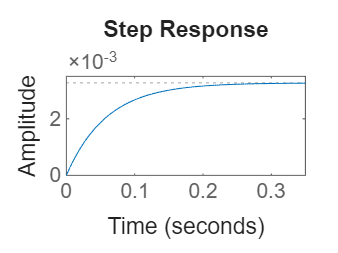

step(sys)

%Finding desired poles
acosd(0)

ans = 90

acosd(1)

ans = 0


p1 = wn; %critical damping
theta1 = 30

theta1 = 30

p2 = wn*(-cosd(theta1) - sind(theta1))

p2 = -6.3996

p3 = wn*(-cosd(theta1) + sind(theta1))

p3 = -1.7148


theta2 = 45

theta2 = 45

p4 = wn*(-cosd(theta2) - sind(theta2))

p4 = -6.6253

p5 = wn*(-cosd(theta2) + sind(theta2))

p5 = 0


syms s
p1 = s+p1

$$p1 = s+\frac{2928}{625}$$

p2 = s+p2

$$p2 = s-\frac{7205259292170163}{1125899906842624}$$

p3 = s + p3

$$p3 = s-\frac{7722573634375351}{4503599627370496}$$

p4 = s + p4

$$p4 = s-\frac{7459433318862185}{1125899906842624}$$

p5 = s + p5

$$p5 = s$$

pretty(collect(p1*p4*p5))

                          2
 3   1365510897053662553 s    273015259470355971 s
s  - ---------------------- - --------------------
       703687441776640000       8796093022208000



Kp = 2.9074e+03 %- 2.898e-70*i

Kp = 2.9074e+03

Ki = 1.1771e+04 %- 1.1591e-69*i

Ki = 11771

Ji = -1.934e+03 %+ 5.7956e-70*i

Ji = -1934

Jp = 0

Jp = 0

Ci = -2.1167e+03

Ci = -2.1167e+03